% known para:

tauA = 35       % N*cm

tauA = 35

AB = 10         % Arm 1

AB = 10

BC = 10         % Arm 2

BC = 10

% these two angle would be iterating
%alpha = pi / 3  % angle of A
beta  = pi / 3  % angle of B

beta = 1.0472

%gamma = pi / 3  % angle of C
theta = pi / 6  % angle theta

theta = 0.5236

AC = SAS(AB,BC,beta)

AC = 10.0000

FC = tauA / AC

FC = 3.5000

FN = FC * sin(theta) 

FN = 1.7500

FL = FC * cos(theta) 

FL = 3.0311

%testing case 1: fixed beta
[alpha, gamma] = angleupdate(beta,AB,BC)

alpha = 1.0472

gamma = 1.0472

%theta range = [-gamma: 2*pi - gamma]

%thetalist = -gamma:0.1:2*pi-gamma; %full range
minr = -30/180*pi;
maxr = 95/180*pi;
thetalist = minr:0.05:maxr;

FNlist = FC * sin(thetalist);
FLlist = FC * cos(thetalist);

figure
plot(thetalist,FNlist,thetalist,FLlist)
legend('FN','FL')

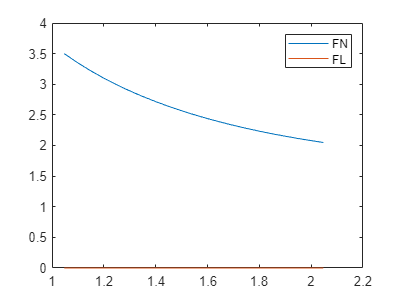

%testing case 2: fixed theta
theta = pi/2;
betalist = pi/3:0.05:2*pi/3;
AClist = SAS(AB,BC,betalist);
FClist = tauA ./ AClist;
FNlist = FClist*sin(theta);
FLlist = FClist*cos(theta);
figure
plot(betalist,FNlist,betalist,FLlist)
legend('FN','FL')

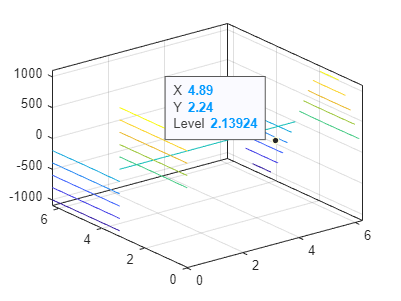

%testing case 3: contour of FN


%testing case 4 contour of FL
